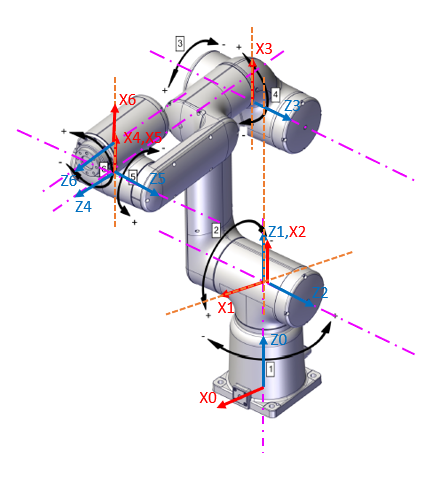

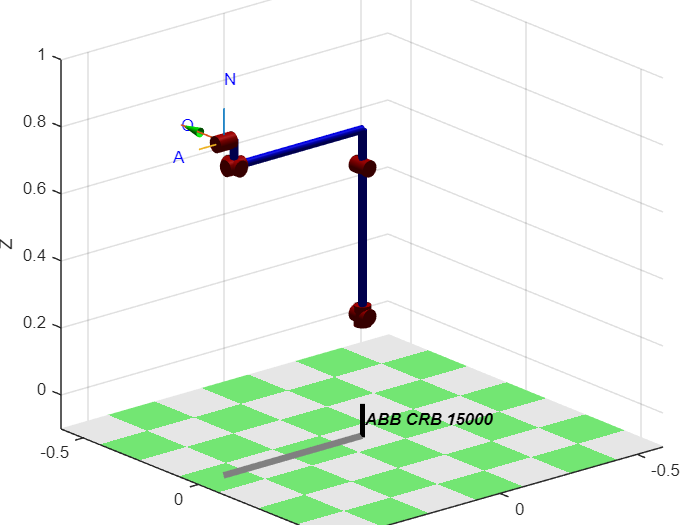

clc
syms theta_1 theta_2 theta_3 theta_4 theta_5 theta_6  
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.037;

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-3.92699 1.48353]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);

Robot_ABB = SerialLink(L,'name','ABB CRB 15000'); 

Robot_ABB.plot([0 0 0 0 0 0],'workspace',[-0.5 0.5 -0.5 0.5 -0.1 1],'scale',0.5,'noa', 'view',[140 20])

**2.1 Con los valores numéricos de longitudes y desplazamientos de los eslabones del robot asignado obtenga el Jacobiano (como una matriz de valores n úmericos, NO simbólico) en funci´on de los ángulos de articulación. ** 

q=[0 0 0 0 0 0];
jacob0(Robot_ABB,q)

ans =     0.0000    0.6340    0.1900    0.0000    0.0800         0
    0.5070    0.0000    0.0000   -0.0800    0.0000         0
         0   -0.5070   -0.5070   -0.0000   -0.0370         0
   -0.0000         0         0    1.0000         0    1.0000
         0    1.0000    1.0000    0.0000    1.0000    0.0000
    1.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000